tested_net = net;
new_fs = 1997/6;
%
ds_test = ds_train;
ds_test.MiniBatchSize = 2;
ds_test.augmentData = false;
features_table = ds_test.read;
features = features_table{:,1};
interactions = features_table{:,2};
labels_vector = features_table{:,2};
features_big = {cat(4,features{:,:})};
features_sqeuuzed = {squeeze(features_big{:,:}(:,26,:,:))};

tested_net = net;
times = [55 60];
new_fs = 330;
inds = (1+times(1)*new_fs):(times(2)*new_fs);
% features = {all_feature(:,:,:,inds)};

features = {all_feature(:,:,:,:)};

Unrecognized function or variable 'all_feature'.

features_big = {cat(4,features{:,:})};
features_sqeuuzed = {squeeze(features_big{:,:}(:,26,:,:))};
labels_vector = {[]};

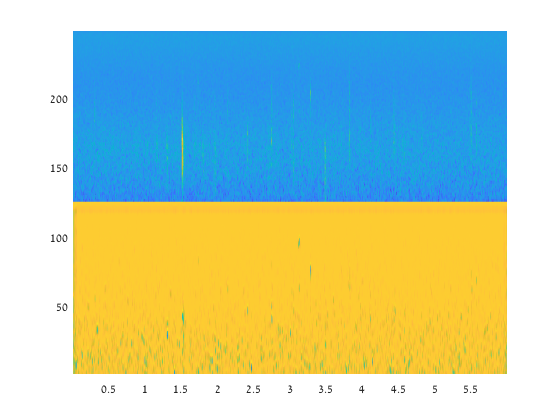

if true
    %     features = {features{:,:}*10+1};
    input_size = size(features,1);
    labels_vector = {cat(2,labels_vector{:,:})};
    file_size = input_size;
    
    
    
    all_features_sample = features_big{:};
    act1 = (activations(tested_net,all_features_sample,'conv_flat_4'));
%     act1 = (activations(tested_net,all_features_sample,'relu_3_5'));
%     act1=dlarray(act1,'SSCB');
%     act1 = sigmoid(act1);
%     act1 = extractdata(act1);
    size(act1);
    if iscell(act1)
        I = act1{:,:};
    else
        [numFeatures,width,numFilters,numTimes]=size(act1);
        mid_section = floor(width/2)+1;
        act1_slice = (act1(:,mid_section,:,:));
        act1_t = permute(act1_slice,[1,2,4,3]);
        act1_t = reshape(act1_t,numFeatures,1,[]);
%         size(act1_t);
        
%         act1_t = act1_t-min(min(min(act1_t)))+eps;
%         act1_t = (act1_t).^2;

        max_act1_t = max(max((act1_t)));
        min_act1_t = min(min((act1_t)));
        
        act1_t = (act1_t-min_act1_t)/(max_act1_t-min_act1_t);
        act1_t = tanh(act1_t);
%         act1_t = exp(act1_t);
        act1_t_coppy = act1_t;
        max_act1_t = max(max((act1_t)));
        % %         max_act1_t = median(act1_t,'all');
%         act1_t((act1_t)<0.1*max_act1_t)=0;
%         act1_t((act1_t)>=0.1*max_act1_t)=1;
     
        % act1_t = (zscore(act1_t));
        I = imtile(mat2gray(act1_t),'GridSize',[numFilters numTimes]);
        I(1:70,:) = 0;
        
        max_min_I = zeros(2,size(I,2));
        for m = 1:size(I,2)
            temp_max_I = find(I(:,m),1,'last');
            temp_min_I = find(I(:,m),1,'first');
            
            if ~isempty(temp_max_I)
                max_min_I(1,m) = temp_max_I;
                max_min_I(2,m) = temp_min_I;
            else
                max_min_I(:,m) = nan;
            end
            
        end
    end
    I_copy = imtile(mat2gray(act1_t_coppy),'GridSize',[numFilters numTimes]);
    figure;
    
    
    %Concatenate the feature map
    map_in_fc = mat2gray(squeeze(all_features_sample(:,26,:,:)));
    act1_t_map = cat(1,I_copy,map_in_fc);
    act1_t_map = mat2gray(act1_t_map);
    
    
%     I = 1-I;
%     act1_t_map = -act1_t_map;
    xTime = (1:numTimes)/new_fs;
    hSurf= surf(act1_t_map,'EdgeColor','none');
    hSurf.XData = (xTime);
    
    axis tight
    colormap gray
    view(2);
end

%Add the location labels


new_fs = 330;
data_in = features_sqeuuzed{:,:};
file_size_bin = size(data_in,2);
file_size_sec = file_size_bin/new_fs;
ypred = predict(tested_net,features_big,'ReturnCategorical',true);
manual_tab = create_table_from_logical_array_only_table(logical(double(labels_vector{:,:})-1),file_size_sec,0);
predicted_tab = create_table_from_logical_array_only_table(logical(double(ypred{:,:})-1),file_size_sec,0);

% predicted_tab = new_tab;
labels_model = [predicted_tab.Onsets,predicted_tab.Offsets];

labels_spect = {[labels_model,(1:size(labels_model,1))'],'Model'};

% labels_spect = {[labels_models,(1:size(labels_model,1))'],'Model';...
%         [manual_tab.Onsets,manual_tab.Offsets,(1:size(manual_tab,1))'],'Manual'};

% labels_spect = {[labels_models,(1:size(labels_model,1))'],'Model';...
%     [labels_ds,(1:size(labels_ds,1))'],'DS'};

labels_spect = {[labels_model-times(1),(1:size(labels_model,1))'],'Model';...
    [labels_ds-times(1),(1:size(labels_ds,1))'],'DS'};

% predicted_tab = new_tab;
% labels_spect = {[labels_model-times(1),(1:size(labels_model,1))'],'Model';...
%     [labels_ds-times(1),(1:size(labels_ds,1))'],'DS';...
%     [labels_manual-times(1),(1:size(labels_manual,1))'],'Manual'};

% predicted_tab = new_tab;
% labels_spect = {[predicted_tab.Onsets,predicted_tab.Offsets,(1:size(predicted_tab,1))'],'Model';...
%     [labels_ds,(1:size(labels_ds,1))'],'DS'};


fs = 2.5e5;
% fs = 332;
winlen_ms = 11;
winlen_s=winlen_ms/1000;
winlen_bin = round(fs*winlen_s);
mode_flag = 2;

% data_in = mat2gray(data_in);
% data_in = 1-data_in;


% spectrogram_browser(data_in,labels_spect,times,[],[],fs,mode_flag);

colormap default
%

temp_ds_box = Calls.Box;
ds_box_bot_h = temp_ds_box(:,[2,4]);
ds_box_bot_top = [ds_box_bot_h(:,1),ds_box_bot_h(:,1)+ds_box_bot_h(:,2)];
ds_box_bot_top = ds_box_bot_top*1000+10000;

%Convert to mel

[~,cF,~] =melSpectrogram(zeros(2.5e5,1),2.5e5, ...
               'WindowLength',2750,...
               'OverlapLength',2000, ...
               'FFTLength',5500, ...
               'NumBands',124, ...
               'FrequencyRange',[1000 125000]);

    sz_ds = size(ds_box_bot_top,1);
    [ ~, ds_bot] = min(abs(ds_box_bot_top(:,1)-repmat(cF,[sz_ds,1])),[],2);
    [ ~, ds_top] =  min(abs(ds_box_bot_top(:,2)-repmat(cF,[sz_ds,1])),[],2);
    

% ds_box_bot_top = (2595*log10(1+(ds_box_bot_top./700)))./(2595*log10(1+(1000/700)))*21.3388 ;
%5.811 = 121khz, 124bands,  1 melkhz = 124/5.811 = 21.3388
%Fix y scale

temp_ds_box(:,2) = ds_bot;
temp_ds_box(:,4) = ds_top-ds_bot;
ds_box = table(temp_ds_box,'VariableNames',{'Box'});

mode_flag = 1;
fs = 330;
% model_box = tab_to_box(new_tab,I,times,new_fs);
 model_box = tab_to_box(predicted_tab,I,[],new_fs);
y_cont = {model_box};
%y_cont = {model_box;ds_box};
% y_cont = {model_box;ds_box;[]};
 
ax2 = spectrogram_browser2(act1_t_map',labels_spect,[],[],[],fs,mode_flag,[],y_cont);
str = sprintf('%0.1f-%0.1f sec',times(1),times(2));
cords =[];
text(ax2,diff(times)*0.98,12,0,str,"BackgroundColor",'white','HorizontalAlignment','right');
colormap default
